# Fórmulas de derivación numérica

## Introducción

blablabla

## Resultados

blablabla

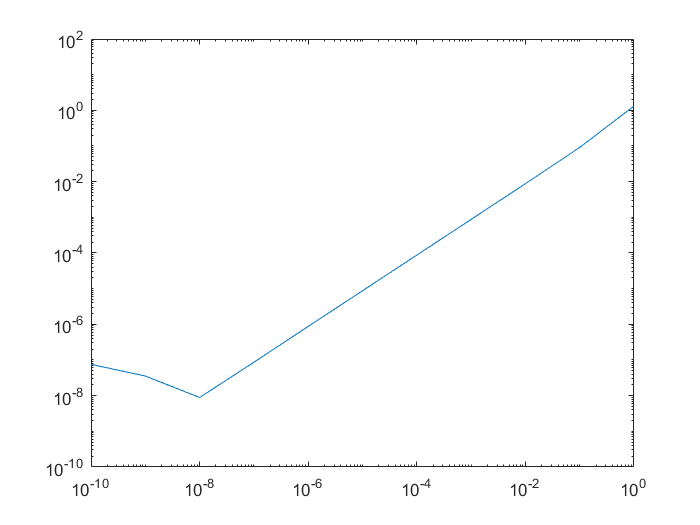

f = @(x) -0.1 * x.^4 - 0.15 * x.^3 - 0.5 * x.^2 - 0.25 * x + 1.2;
x = 0.5;
h = 1;
n = 11;

[hs, error] = firstDerForwardOrder1(f, x, h, n);
loglog(hs, error)

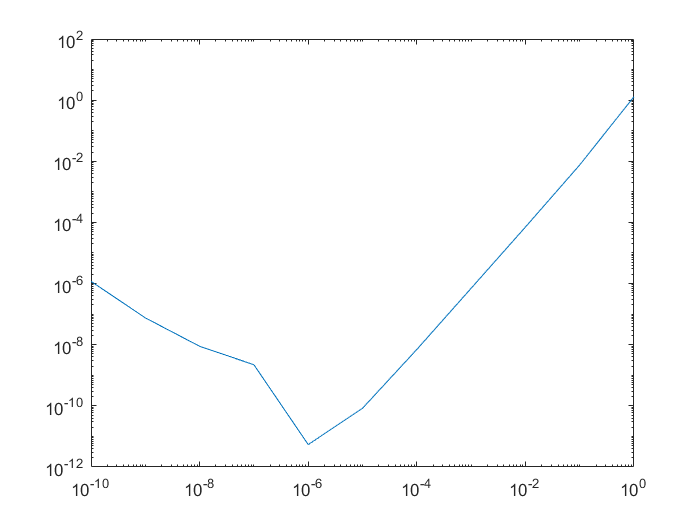

[hs, error] = firstDerForwardOrder2(f, x, h, n);
loglog(hs, error)

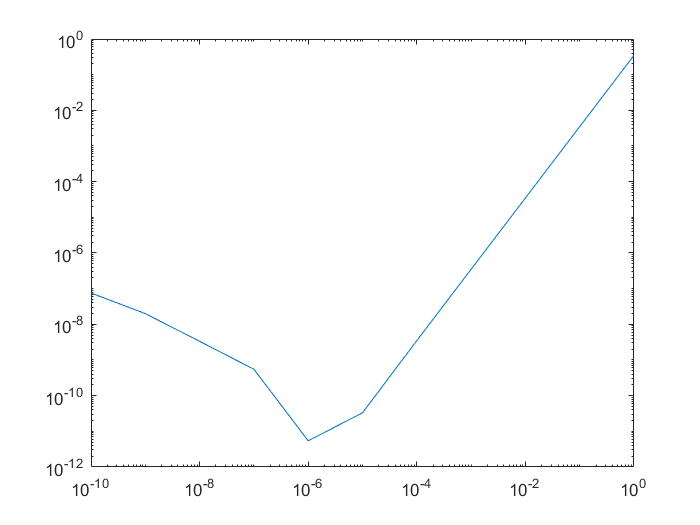

[hs, error] = firstDerCentral(f, x, h, n);
loglog(hs, error)

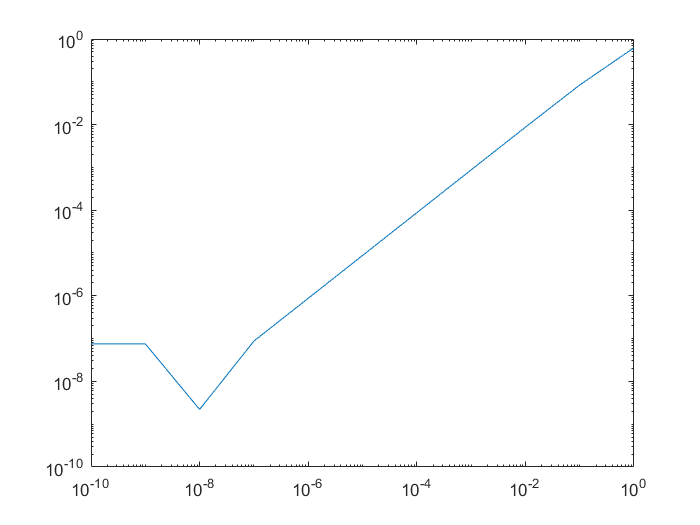

[hs, error] = firstDerBackwardOrder1(f, x, h, n);
loglog(hs, error)

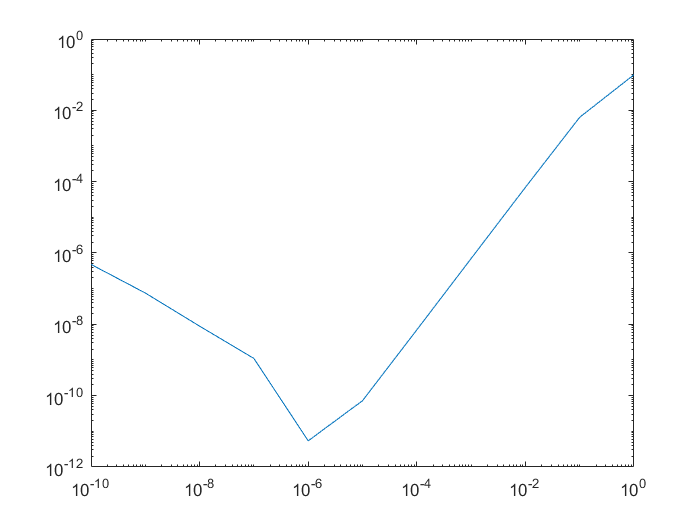

[hs, error] = firstDerBackwardOrder2(f, x, h, n);
loglog(hs, error)

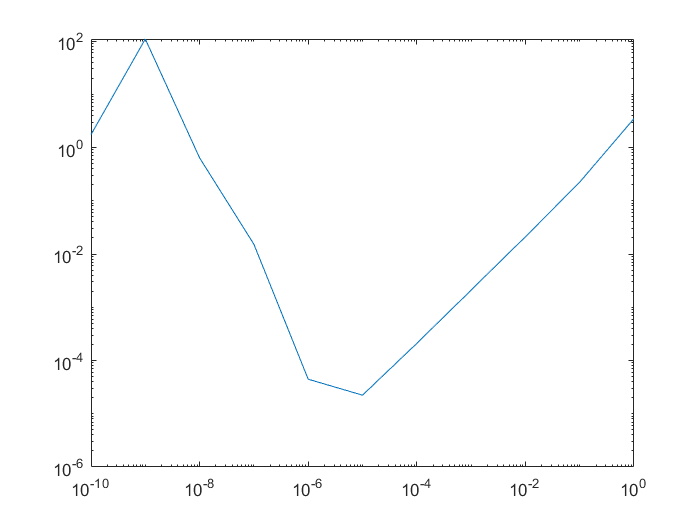

[hs, error] = secondDerForwardOrder1(f, x, h, n);
loglog(hs, error)

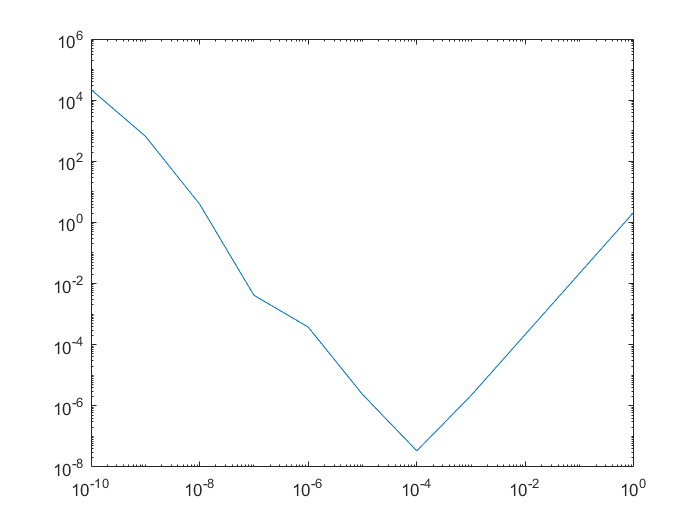

[hs, error] = secondDerForwardOrder2(f, x, h, n);
loglog(hs, error)

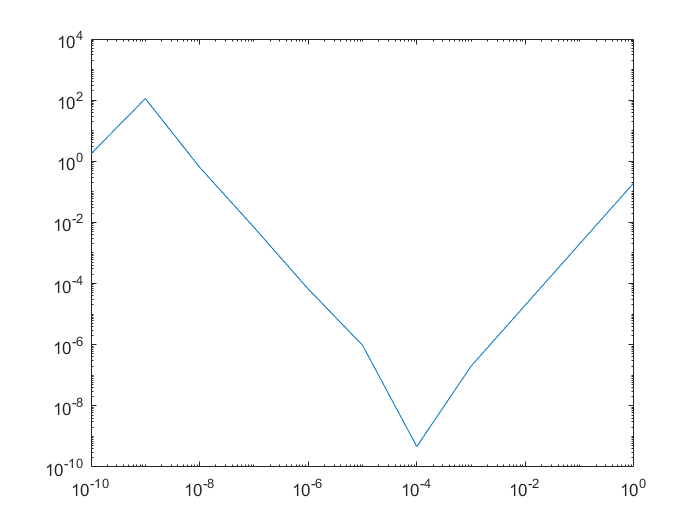

[hs, error] = secondDerCentral(f, x, h, n);
loglog(hs, error)

## Conclusiones

blablabla

## Funciones

Se desarrollaron las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada; $O\left(h\right)$ y $O\left(h^2 \right)$. Es importante notar que para las aproximaciones centradas, unicamente se presentan las correspondientes a $O\left(h^2 \right)$.

### Primera derivada

Para la primera derivada, se exponen las siguientes funciones:

- Aproximación hacia adelante: $O\left(h\right)$

- Aproximación hacia adelante: $O\left(h^2 \right)$

- Aproximación centrada: $O\left(h^2 \right)$

- Aproximación hacia atrás: $O\left(h\right)$

- Aproximación hacia atrás: $O\left(h^2 \right)$

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x+h\right)-f\left(x\right)}{h}$

function [hs, err] = firstDerForwardOrder1(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(dfx - (f(x + h) - fx) / h);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{-\frac{1}{2}f\left(x+2h\right)+2f\left(x+h\right)-\frac{3}{2}f\left(x\right)}{h}=\frac{-f\left(x+2h\right)+4f\left(x+h\right)-3f\left(x\right)}{2h}$

function [hs, err] = firstDerForwardOrder2(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(dfx - (-f(x + 2 * h) + 4 * f(x + h) - 3 * fx) / (2 * h));
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{1}{2}f\left(x+h\right)-\frac{1}{2}f\left(x-h\right)}{h}=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$

function [hs, err] = firstDerCentral(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(dfx - (f(x + h) - f(x - h)) / (2 * h));
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end

#### Aproximación hacia atrás

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h}$

function [hs, err] = firstDerBackwardOrder1(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(dfx - (fx - f(x - h)) / h);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{3}{2}f\left(x\right)-2f\left(x-h\right)+\frac{1}{2}f\left(x-2h\right)}{h}=\frac{3f\left(x\right)-4f\left(x-h\right)+f\left(x-2h\right)}{2h}$

function [hs, err] = firstDerBackwardOrder2(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));
    dfx = df(x);
    hs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(dfx - (3 * fx - 4 * f(x - h) + f(x - 2 * h)) / (2 * h));
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end

### Segunda derivada

Para la segunda derivada, se exponen las siguientes funciones:

- Aproximación hacia adelante: $O\left(h\right)$

- Aproximación hacia adelante: $O\left(h^2 \right)$

- Aproximación centrada: $O\left(h^2 \right)$

Las aproximaciones hacia atrás no se codificaron debido a que están compuestas por las mismas fórmulas que las aproximaciones hacia adelante de su respecitvo orden.

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h\right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+2h\right)-2f\left(x+h\right)+f\left(x\right)}{h^2 }$

function [hs, err] = secondDerForwardOrder1(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(ddfx - (f(x + 2 * h) - 2 * f(x + h) + fx) / h ^ 2);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{-f\left(x+3h\right)+4f\left(x+2h\right)-5f\left(x+h\right)+2f\left(x\right)}{h^2 }$

function [hs, err] = secondDerForwardOrder2(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(ddfx - (-f(x + 3 * h) + 4 * f(x + 2 * h) - 5 * f(x + h) + 2 * fx) / h ^ 2);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$

function [hs, err] = secondDerCentral(f, x, h, n)
    if nargin(f) == 0
        error('Es una constante.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        err(i) = abs(ddfx - (f(x + h) - 2 * fx + f(x - h)) / h ^ 2);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end